# **[2024년 1학기 확률 최적 제어] Inventory Model 시뮬레이션 예제**

- **교과목** : 2024년 1학기 제어시스템특론

- **작성자** : 서울시립대학교 전자전기컴퓨터공학부 박경훈 교수([gyunghoon.park@uos.ac.kr](http://gyunghoon.park@uos.ac.kr)) 

본 예제에서는 [Stanford University EE365](https://web.stanford.edu/class/ee365/index.html) 교과목의 [04. Markov Chains](https://web.stanford.edu/class/ee365/lectures/markov.pdf) 강의 교안에 수록된 Inventory model 시뮬레이션 예제를 구현하기 위해 제작되었습니다. 

**주의사항**

- 본 예제에서는 [Statistics and Machine Learning Toolbox](https://www.mathworks.com/products/statistics.html)의 일부 함수를 사용하고 있습니다. 

- 본 예제는 MATLAB 2023b 버젼에서 작성되었습니다. 2023b 이상 버젼에서의 구동을 권장합니다.

#### 초기화

clc;
close all;
clear all;

#### 문제 설정

다음의 비선형 확률 동적 시스템


$$x_{t+1}=[x_t - d_t + u_t]_{[0,C]},\quad u_t = \mu(x_t) = \begin{cases} C-x_t, & \text{if}~x_t\leq 1,\\ 0, & \text{otherwise} \end{cases}$$


을 다양한 방식으로 구현합니다. 이를 위해 필요한 상수들을 전역 혹은 지역 변수로 선언합니다.

global capacity;    capacity = 6;
global probDemand;  probDemand = {0.7, 0.2, 0.1};

numOfState = 7;
timeSim = 150;
initialState = capacity;

#### 구현법 1 : 확률 동적 시스템 표현법

확률 동적 시스템의 상태변수 $x_t$인 `state(t-1)`를 초기화합니다. (MATLAB의 인덱싱 법칙으로 인해 시간 $t$와 `state`의 인덱스 `t-1`가 1칸씩 차이가 있음에 유념합시다.)

state = zeros(1,timeSim);
state(1) = initialState;

이제 다음의 `for` 문을 통해 매 시간마다 확률 변수인 `demand` $d_t$를 생성하고, 이를 이용하여 시스템의 상태변수 $x_t$를 업데이트합니다.

for t = 0:timeSim-1
    demand = generateDemand();
    state(t+2) = updateSystem(state(t+1), demand);  
end

결과를 아래와 같이 출력합니다.

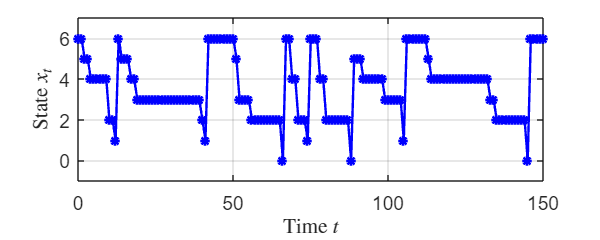

f = figure;
f.Position = [100 100 500 200];

plot(0:timeSim, state, 'b', 'LineWidth', 1.5, 'Marker','*');
grid on;
xlabel('Time $t$', 'Interpreter', 'latex');
ylabel('State $x_t$', 'Interpreter', 'latex');
ylim([-1 7]);
set(gca, 'fontsize', 12);

#### 구현법 2 : 천이 행렬 표현법

이제 동일한 시스템을 다른 방식으로 시뮬레이션해봅시다. 교안에 따르면 위의 시스템의 거동은 다음의 graph로도 설명이 가능합니다.

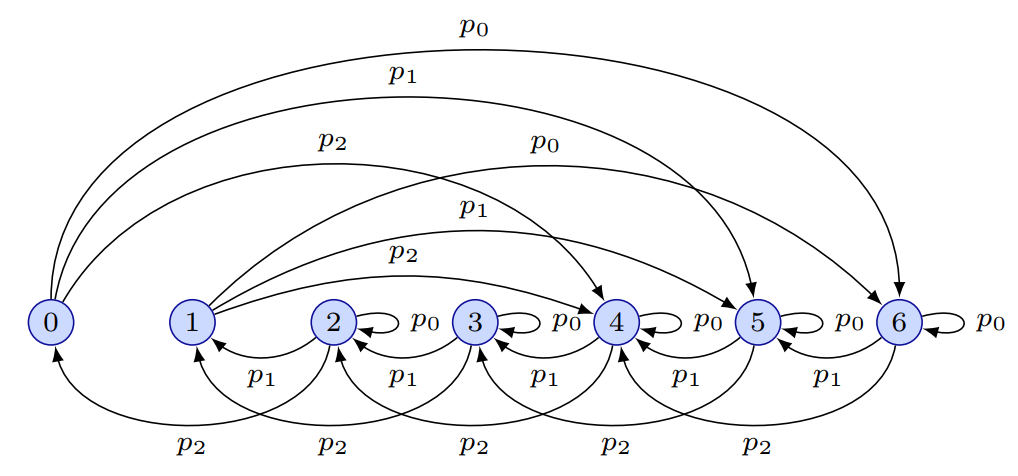

위의 시스템을 다음의 transition matrix


$$P=[P_{ij}],\quad P_{ij} = {\bf Prob}\big( x_{t+1}=j~|~x_t = i \big)$$


를 이용하여 시뮬레이션합니다. 

필요한 상수와 변수를 선언 및 초기화합니다.

state = zeros(1,timeSim);
state(1) = initialState;
r = 0;
sumProb = 0;

global listState;
listState = [0, 1, 2, 3, 4, 5, 6];

p0 = probDemand{1};
p1 = probDemand{2};
p2 = probDemand{3};
transMat = [...
            0, 0, 0, 0, p2, p1, p0;...
            0, 0, 0, 0, p2, p1, p0;...
            p2, p1, p0, 0, 0, 0, 0;...
            0, p2, p1, p0, 0, 0, 0;...
            0, 0, p2, p1, p0, 0, 0;...
            0, 0, 0, p2, p1, p0, 0;...
            0, 0, 0, 0, p2, p1, p0
            ];

그리고 transition matrix $P$를 이용하여 정의된 `updateSystem2(state, transMat)` 함수를 이용하여 다시 모의실험합니다.

for t = 0:timeSim-1
    state(t+2) = updateSystem2(state(t+1), transMat);      
end

결과를 다음과 같이 도식화합니다.

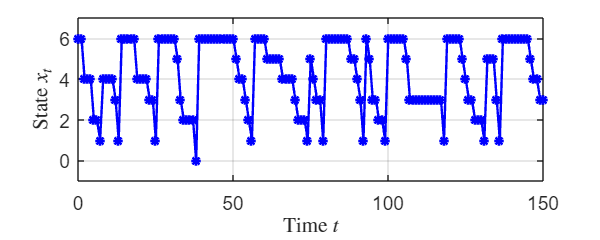

f = figure;
f.Position = [100 100 500 200];

plot(0:timeSim, state, 'b', 'LineWidth', 1.5, 'Marker','*');
grid on;
xlabel('Time $t$', 'Interpreter', 'latex');
ylabel('State $x_t$', 'Interpreter', 'latex');
xlim([0 150]);
ylim([-1.0 7.0]);

set(gca, 'fontsize', 12);

#### Distribution propagation

상태변수의 transition이 진행됨에 따라, 상태변수 $(x_t)_i$에 대한 distribution인 $(\pi_t)_i$의 값이 시간에 따라 변하게 됩니다. 특히 Markov chain 특성을 가지는 시스템에 대하여


$$\pi_{t+1}=\pi_t P$$


를 얻는데, 아래에서는 위의 수식에 따른 $\pi_t$의 변화를 살펴보겠습니다. 

필요한 변수를 초기화합니다.

distState = zeros(timeSim + 1, numOfState);
distState(1,:) = [0, 0, 0, 0, 0, 0, 1];

그리고 시간이 진행됨에 따라 $\pi_{t+1}=\pi_t P$를 구현합니다.

for t = 0:timeSim-1
    distState(t+2,:) = distState(t+1,:)*transMat;
end

이제 그 결과를 `subplot` 함수를 이용하여 그립니다.

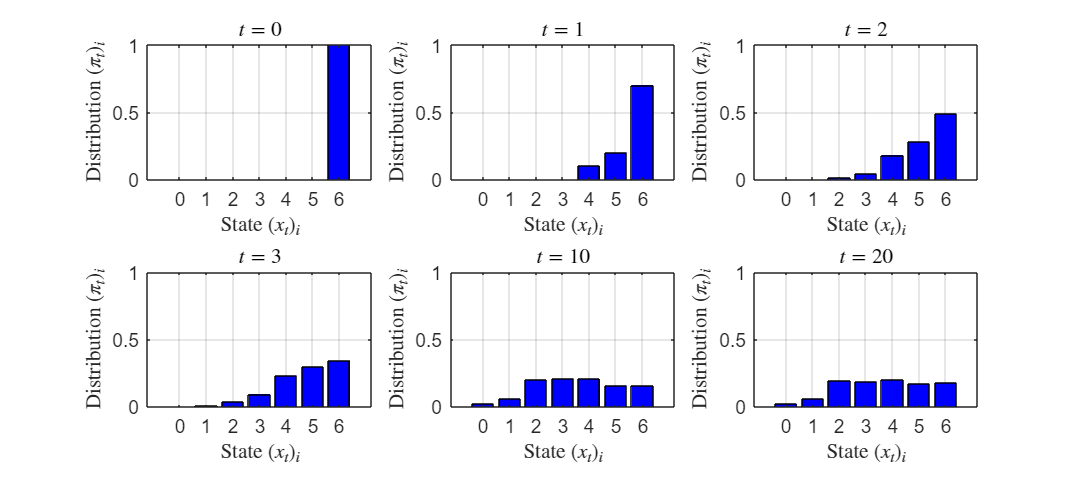

f = figure;
f.Position = [100 100 900 400];

subplot(2,3,1)
    bar(listState, distState(1,:), 'b');
    grid on;
    xlabel('State $(x_{t})_i$', 'Interpreter', 'latex');
    ylabel('Distribution $(\pi_t)_i$', 'Interpreter', 'latex');
    title('$t=0$','Interpreter','latex');
    ylim([0 1]);
    set(gca, 'fontsize', 12);    
subplot(2,3,2)
    bar(listState, distState(2,:), 'b');
    grid on;
    xlabel('State $(x_{t})_i$', 'Interpreter', 'latex');
    ylabel('Distribution $(\pi_t)_i$', 'Interpreter', 'latex');
    title('$t=1$','Interpreter','latex');
    ylim([0 1]);
    set(gca, 'fontsize', 12);    
subplot(2,3,3)
    bar(listState, distState(3,:), 'b');
    grid on;
    xlabel('State $(x_{t})_i$', 'Interpreter', 'latex');
    ylabel('Distribution $(\pi_t)_i$', 'Interpreter', 'latex');
    title('$t=2$','Interpreter','latex');
    ylim([0 1]);
    set(gca, 'fontsize', 12);    
subplot(2,3,4)
    bar(listState, distState(4,:), 'b');
    grid on;
    xlabel('State $(x_{t})_i$', 'Interpreter', 'latex');
    ylabel('Distribution $(\pi_t)_i$', 'Interpreter', 'latex');
    title('$t=3$','Interpreter','latex');
    ylim([0 1]);
    set(gca, 'fontsize', 12);    
subplot(2,3,5)
    bar(listState, distState(11,:), 'b');
    grid on;
    xlabel('State $(x_{t})_i$', 'Interpreter', 'latex');
    ylabel('Distribution $(\pi_t)_i$', 'Interpreter', 'latex');
    title('$t=10$','Interpreter','latex');
    ylim([0 1]);
    set(gca, 'fontsize', 12);
subplot(2,3,6)
    bar(listState, distState(21,:), 'b');
    grid on;
    xlabel('State $(x_{t})_i$', 'Interpreter', 'latex');
    ylabel('Distribution $(\pi_t)_i$', 'Interpreter', 'latex');
    title('$t=20$','Interpreter','latex');
    ylim([0 1]);
    set(gca, 'fontsize', 12);

위의 계산을 이용하면 시스템의 상태변수에 대한 다양한 확률을 계산할 수 있습니다. 예를 들어 ${\bf Prob}(x_t \in \{ 0,1 \})$는 $(\pi_t)_0 + (\pi_t)_1$로 표현되는데, 이는 시간이 지남에 따라 아래와 같이 그려집니다.

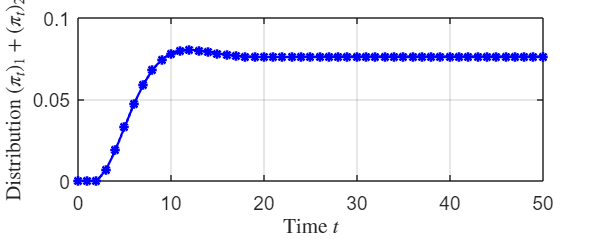

f = figure;
f.Position = [100 100 500 200];

plot(0:timeSim, distState(:,1) + distState(:,2), 'b', 'LineWidth', 1.5, 'Marker','*');
grid on;
xlabel('Time $t$', 'Interpreter', 'latex');
ylabel('Distribution $(\pi_t)_{0} + (\pi_t)_{1}$', 'Interpreter', 'latex');
xlim([0 50]);
ylim([0 0.1]);
set(gca, 'fontsize', 12);

유사하게 ${\bf Prob}(x_t \in \{ 2,3 \})$을 나타내는 $(\pi_t)_2 + (\pi_t)_3$는 다음과 같이 그려집니다. (여기서 위의 그림과 y축의 스케일이 크게 다름에 유념합시다.)

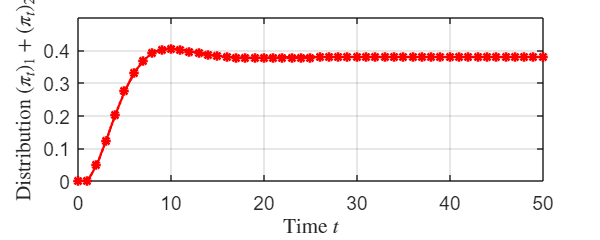

f = figure;
f.Position = [100 100 500 200];

plot(0:timeSim, distState(:,3) + distState(:,4), 'r', 'LineWidth', 1.5, 'Marker','*');
grid on;
xlabel('Time $t$', 'Interpreter', 'latex');
ylabel('Distribution $(\pi_t)_{1} + (\pi_t)_{2}$', 'Interpreter', 'latex');
xlim([0 50]);
ylim([0 0.5]);
set(gca, 'fontsize', 12);

#### 지역 함수 정의

`updateSystem(state, demand)` 함수에서는, `demand` $d_t$가 주어져있을 때 refill policy인 $u_t = \mu_t(x_t)$가 적용된 폐루프 시스템의 다음 상태변수값인 $x_{t+1}$을 계산합니다.

function nextState = updateSystem(state, demand)
    global capacity;
    if (state <= 1)
        policy = capacity - state;
    else
        policy = 0;
    end    
    nextState = state - demand + policy;
    if (nextState <= 0)
        nextState = 0;
    elseif (nextState >= capacity)
        nextState = capacity;
    end
end

`generateDemand()` 함수에서는 확률 변수 $r\sim {\rm Unif}([0,1])$를 생성한 후, 그 값에 따라 $d_t$를 $\{  0,1,2 \}$ 중 하나로 출력합니다.

function demand = generateDemand()
    global probDemand;
    r = unifrnd(0,1);
    if (r <= probDemand{1})
        demand = 0;
    elseif (r <= probDemand{1}+probDemand{2})
        demand = 1;
    else
        demand = 2;
    end
end

`updateSystem2(state, transMat)` 함수는 현재 상태변수인 $x_t$와 transition matrix인 $P$를 받아서 graph 표현법으로 표현된 확률 동적 시스템의 다음 상태변수값인 $x_{t+1}$를 반환합니다.

function nextState = updateSystem2(state, transMat)
    global listState;
    r = unifrnd(0,1);
    listProb = transMat(state+1,:);    
    for idx = 1:7
        if idx == 1
            if (r < sum(listProb(1:idx)))
                nextState = listState(idx);
            end
        else                
            if (sum(listProb(1:idx-1)) <= r) && (r < sum(listProb(1:idx)))
                nextState = listState(idx);
            end
        end
    end
end